# **Laboratorio 4**

# **Modelo Cinemátco Directo**

**Nikolai****Alexander Cáceres Penagos – Andrés Felipe Forero Salas - ****Ivan****Mauricio Hernández Triana**

Se trabaja con la versión actualizada del Robot Phantom X, teniendo en cuenta lo anterior se tomaron las medidas que permiten encontrar los parámetros DHstd para el robot. A continuación se muestra un esquema ilustrativo de su configuración.

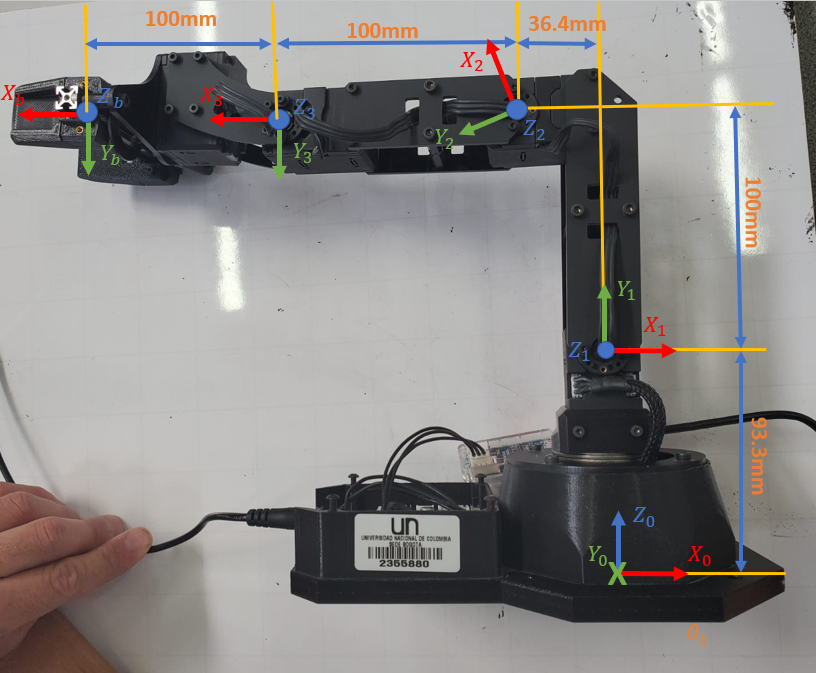

Teniendo en cuenta este diagrama, se encuentran los parámetros de articulación y eslabón para el manipulador.

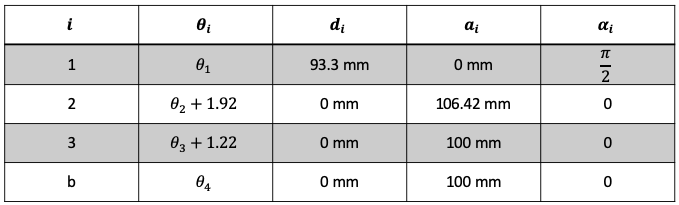

Con estos parámetros se hallan las matrices de transformación homogéneas para cada uno de los sistemas.

syms O1 O2 O3 O4

T10 = MTH(O1,93.3,0,90,2) %En radianes O1

$$T10 = \left(\begin{array}{cccc} \cos\left(O_{1}\right) & 0 & \sin\left(O_{1}\right) & 0\\ \sin\left(O_{1}\right) & 0 & -\cos\left(O_{1}\right) & 0\\ 0 & 1 & 0 & \frac{933}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T21 = MTH(O2+1.92,0,106.42,0,2)  %En radianes O2

$$T21 = \left(\begin{array}{cccc} \cos\left(O_{2}+\frac{48}{25}\right) & -\sin\left(O_{2}+\frac{48}{25}\right) & 0 & \frac{5321\,\cos\left(O_{2}+\frac{48}{25}\right)}{50}\\ \sin\left(O_{2}+\frac{48}{25}\right) & \cos\left(O_{2}+\frac{48}{25}\right) & 0 & \frac{5321\,\sin\left(O_{2}+\frac{48}{25}\right)}{50}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T32 = MTH(O3+1.22,0,100,0,2)  %En radianes 

$$T32 = \left(\begin{array}{cccc} \cos\left(O_{3}+\frac{61}{50}\right) & -\sin\left(O_{3}+\frac{61}{50}\right) & 0 & 100\,\cos\left(O_{3}+\frac{61}{50}\right)\\ \sin\left(O_{3}+\frac{61}{50}\right) & \cos\left(O_{3}+\frac{61}{50}\right) & 0 & 100\,\sin\left(O_{3}+\frac{61}{50}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Tb3 = MTH(O4,0,100,0,2)  %En radianes O

$$Tb3 = \left(\begin{array}{cccc} \cos\left(O_{4}\right) & -\sin\left(O_{4}\right) & 0 & 100\,\cos\left(O_{4}\right)\\ \sin\left(O_{4}\right) & \cos\left(O_{4}\right) & 0 & 100\,\sin\left(O_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Finalmente se puede encontrar el modelo geométrico directo, a través del modelo interno de la cadena cinemática.

Tb0 = T10*T21*T32*Tb3

Teniendo en cuenta las configuraciones especificadas; se encuentra la posición y orientación del último sistema coordenado respecto al marco {0}. La orientación se expresa en ángulos de Euler.

qz = [0 0 0 0 0];
Tb0s0 = double(subs(Tb0,[O1 O2 O3 O4],qz(1:4)));
poses0 = [Tb0s0(1:3,4);tr2eul(Tb0s0,'deg')']

poses0 =  -236.4113
         0
  193.6156
  -90.0000
   90.0000
  -90.0913



q1 = [-20 20 -20 20 0]*(pi/180);
Tb0s1 = double(subs(Tb0,[O1 O2 O3 O4],q1(1:4)));
poses1 = [Tb0s1(1:3,4);tr2eul(Tb0s1,'deg')']

poses1 =  -246.6131
   89.7598
  140.9200
 -110.0000
   90.0000
  -70.0913



q2 = [30 -30 30 -30 0]*(pi/180);
Tb0s2 = double(subs(Tb0,[O1 O2 O3 O4],q2(1:4)));
poses2 = [Tb0s2(1:3,4);tr2eul(Tb0s2,'deg')']

poses2 =  -145.5420
  -84.0287
  248.4029
  -60.0000
   90.0000
 -120.0913



q3 = [-90 15 -55 17 0]*(pi/180);
Tb0s3= double(subs(Tb0,[O1 O2 O3 O4],q3(1:4)));
poses3 = [Tb0s3(1:3,4);tr2eul(Tb0s3,'deg')']

poses3 =          0
  229.5421
  284.0861
  180.0000
   90.0000
 -113.0913



q4 = [-90 45 -55 45 10]*(pi/180);
Tb0s4 = double(subs(Tb0,[O1 O2 O3 O4],q4(1:4)));
poses4 = [Tb0s4(1:3,4);tr2eul(Tb0s4,'deg')']

poses4 =          0
  276.9149
   98.5563
  180.0000
   90.0000
  -55.0913


% Posicion de recogida.
q5 = [0 -110 -90 5 0]*(pi/180);

Haciendo uso ahora del metodo de serial link se tiene:

% Usando el metodo de serial link
% Definiendo los parametros DH de manera comoda.
%a_i = [0 1.0642 1 1]; En dm
a_i = [0 10.642 10.0 10.0]; % En cm
%a_i = [0 0.10642 0.1 0.1]; En m
alfa_i = [pi/2 0 0 0];
%d_i = [0.933 0 0 0]; % En dm.
d_i = [9.33 0 0 0]; % En cm.
%d_i = [0.0933 0 0 0]; % En m.
teta_i = [0 1.921 1.221 0];1.75

ans = 1.7500


L(1) = Link('revolute','alpha',alfa_i(1),'a',a_i(1),'d',d_i(1),'offset',teta_i(1),'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',alfa_i(2),'a',a_i(2),'d',d_i(2),'offset',teta_i(2),'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',alfa_i(3),'a',a_i(3),'d',d_i(3),'offset',teta_i(3),'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',alfa_i(4),'a',a_i(4),'d',d_i(4),'offset',teta_i(4),'qlim',[-pi pi]);

q=[0 0 0 0];
ws = [-60 60 -60 60 -30 60];
plot_options = {'workspace',ws,'scale',.9};
Robot = SerialLink(L,'name','Robot','plotopt',plot_options)

 
Robot = 
 
Robot (4 axis, RRRR, stdDH, fastRNE)                             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       9.33|          0|      1.571|          0|
|  2|         q2|          0|      10.64|          0|      1.921|
|  3|         q3|          0|         10|          0|      1.221|
|  4|         q4|          0|         10|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              
       9.81         0  0  1  0           0  0  1  0              
                    0  0  0  1           0  0  0  1            

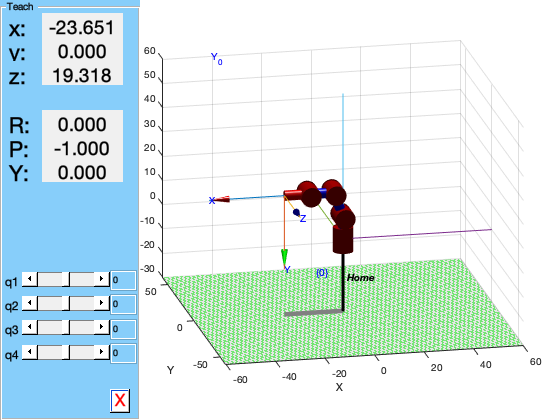

figure
Robot.name = 'Home';
Robot.teach([0 0 0 0])
hold on
%trplot(eye(4),'rgb', 'width',2)
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
%view([2 -2 2])
view([-12 17])

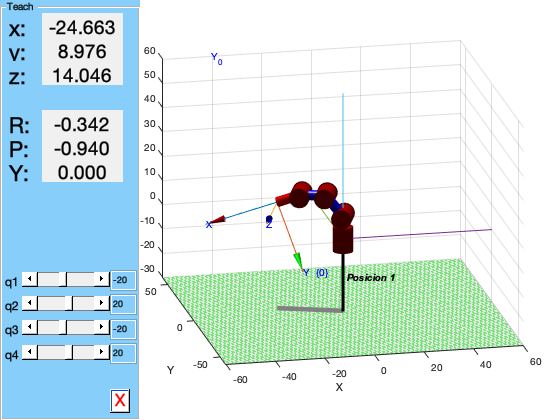

figure
Robot.name = 'Posicion 1';
Robot.teach(q1(1:4));
hold on
%trplot(eye(4),'rgb', 'width',2)
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
%view([2 -2 2])
view([-12 17])

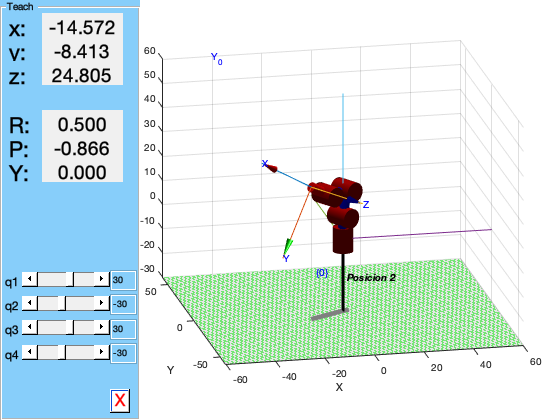

figure
Robot.name = 'Posicion 2';
Robot.teach(q2(1:4));
hold on
%trplot(eye(4),'rgb', 'width',2)
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
%view([2 -2 2])
view([-12 17])

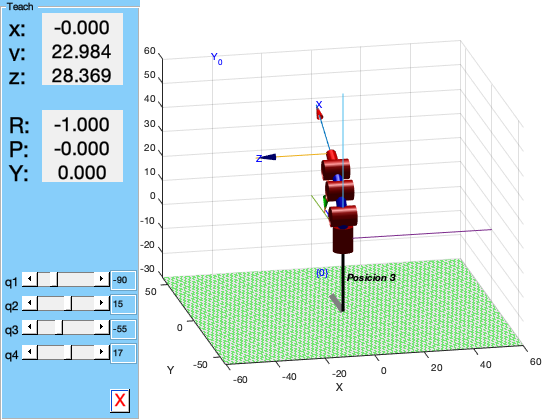

figure
Robot.name = 'Posicion 3';
Robot.teach(q3(1:4));
hold on
%trplot(eye(4),'rgb', 'width',2)
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
%view([2 -2 2])
view([-12 17])

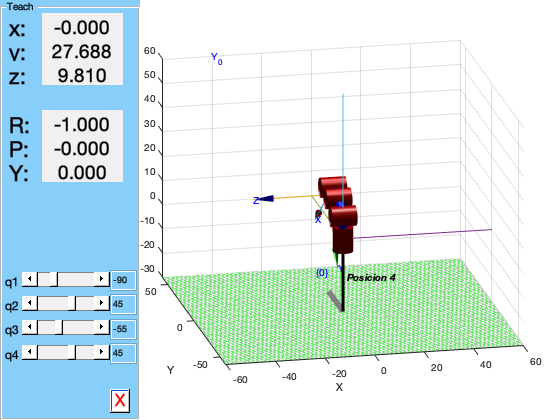

figure
Robot.name = 'Posicion 4';
Robot.teach(q4(1:4));
hold on
%trplot(eye(4),'rgb', 'width',2)
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
%view([2 -2 2])
view([-12 17])

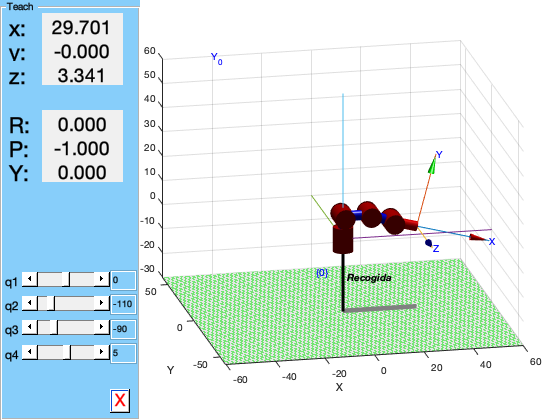

figure
Robot.name = 'Recogida';
Robot.teach(q5(1:4));
hold on
%trplot(eye(4),'rgb', 'width',2)
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
%view([2 -2 2])
view([-12 17])

function [H] = MTH(thetai,di,ai,alphai,angleType)
%Hecho por Andrés Felipe Forero Salas
%Función para calcular la Matriz de Transformación Homogénea
%dados los parámetros DHstd en diferentes posibles sistemas
%numéricos
    if angleType == 0 %rad
        H = [cos(thetai) -sin(thetai)*cos(alphai) sin(thetai)*sin(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cos(alphai) -cos(thetai)*sin(alphai) ai*sin(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    elseif angleType == 1 %degrees
        H = [cosd(thetai) -sind(thetai)*cosd(alphai) sind(thetai)*sind(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cosd(alphai) -cosd(thetai)*sind(alphai) ai*sind(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 2 %thetai en rad, alphai en degree
        H = [cos(thetai) -sin(thetai)*cosd(alphai) sin(thetai)*sind(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cosd(alphai) -cos(thetai)*sind(alphai) ai*sin(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 3 %thetai en degree, alphai en rad
        H = [cosd(thetai) -sind(thetai)*cos(alphai) sind(thetai)*sin(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cos(alphai) -cosd(thetai)*sin(alphai) ai*sind(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    end
end